# Gauss Seidel Method

## Solution of x in Ax=b using Gauss Seidel Method

- ***Initialize 'A' 'b' & intial guess 'x'***

A=[5 -2 3 0 6; -3 9 1 -2 7.4; 2 -1 -7 1 6.7; 4 3 -5 7 9; 2 3.5 6.1 -4 -8.1]

A =     5.0000   -2.0000    3.0000         0    6.0000
   -3.0000    9.0000    1.0000   -2.0000    7.4000
    2.0000   -1.0000   -7.0000    1.0000    6.7000
    4.0000    3.0000   -5.0000    7.0000    9.0000
    2.0000    3.5000    6.1000   -4.0000   -8.1000


b=[-1 2 3 0.5 3.1]'

b =    -1.0000
    2.0000
    3.0000
    0.5000
    3.1000


x=rand(5,1)

x =     0.1576
    0.9706
    0.9572
    0.4854
    0.8003


n=size(x,1);
normVal=Inf; 

- ***Tolerence for method***

tol=1e-3; GaussItr=0;

## Algorithm: Gauss Seidel Method

plotGauss=[];
while normVal>tol
    x_old=x;
    
    for i=1:n
        
        sigma=0;
        
        for j=1:i-1
                sigma=sigma+A(i,j)*x(j);
        end
        
        for j=i+1:n
                sigma=sigma+A(i,j)*x_old(j);
        end
        
        x(i)=(1/A(i,i))*(b(i)-sigma);
    end
    
    GaussItr=GaussItr+1;
    normVal=norm(x_old-x);
    plotGauss=[plotGauss;normVal];
end

fprintf('Solution of the system is : \n%f\n%f\n%f\n%f\n%f in %d iterations',x,GaussItr);

Solution of the system is : 
0.550734
0.469135
-0.595497
-0.648601
-0.172184 in 98 iterations

# Jacobi Method

## Solution of x in Ax=b using Jacobi Method

- ***intial guess 'x'***

x=rand(5,1)

x =     0.1419
    0.4218
    0.9157
    0.7922
    0.9595



n=size(x,1);
normVal=Inf; 
JacobItr=0;

## Algorithm: Jacobi Method

plotJacobi=[];
while normVal>tol
    xold=x;
    
    for i=1:n
        sigma=0;
        
        for j=1:n
            
            if j~=i
                sigma=sigma+A(i,j)*x(j);
            end
            
        end
        
        x(i)=(1/A(i,i))*(b(i)-sigma);
    end
    
    JacobItr=JacobItr+1;
    normVal=norm(xold-x);
    plotJacobi=[plotJacobi;normVal];
end
fprintf('Solution of the system is : \n%f\n%f\n%f\n%f\n%f in %d iterations',x,JacobItr);

Solution of the system is : 
0.550693
0.469148
-0.595537
-0.648571
-0.172233 in 98 iterations

## Comparison: Gauss Seidel Method Vs Jacobi Method

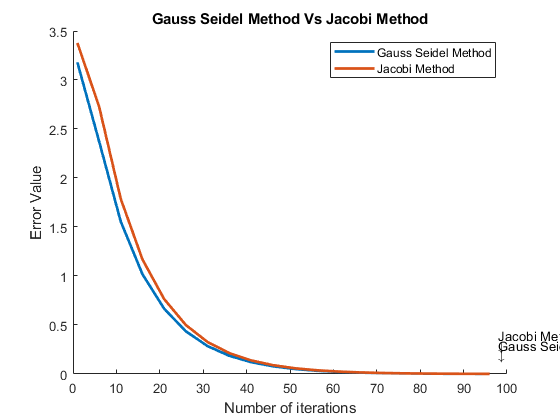

figure
hold on
plot(1:5:GaussItr,plotGauss(1:5:GaussItr),'LineWidth',2)
plot(1:5:JacobItr,plotJacobi(1:5:JacobItr),'LineWidth',2)
text(GaussItr,0.2,'\downarrow')
text(GaussItr,0.3,'Gauss Seidel')
text(JacobItr,0.3,'\downarrow')
text(JacobItr,0.4,'Jacobi Method')
legend('Gauss Seidel Method','Jacobi Method')
ylabel('Error Value')
xlabel('Number of iterations')
title('Gauss Seidel Method Vs Jacobi Method')
hold off